# **Consecutive NaN Analysis in Single-Visit Light Curves**

### **Objective**

We investigate the occurrence of consecutive NaN values within individual visit light curves. By identifying light curves with an excessive number of consecutive NaNs, we aim to characterize potential false positives and uncover potential instrumental or atmospheric effects affecting multiple sources within a subframe. Since faint targets might disappear while in transit we would like to estimate the amount of adjecent no detection points in LAST data.

#### **Methodology**

- **Data Preparation:** Single-visit light curves are divided into magnitude bins for analysis.

- **NaN Identification:** Consecutive NaN sequences are determined for each light curve.

- **False Positive Rate Estimation:** The frequency of light curves with a specified number of consecutive NaNs is calculated to estimate a false positive rate.

- **Source Comparison:** Light curves exhibiting similar NaN patterns are grouped to identify potential instrumental or atmospheric impacts.

#### **Expected Outcomes**

- Characterization of the false positive rate associated with consecutive NaNs.

- Identification of potential instrumental or atmospheric artifacts through the analysis of correlated NaN patterns.

- Insights into data quality and reliability.

By understanding the distribution of consecutive NaN values and their impact on light curve analysis, this script contributes to improving data quality assessment and the identification of systematic errors.

#### **Notes**

- Data set will be changed/

- For now grouping light curves per Mag

true% load data

ans = logical
   1


%cd('/Users/yarinms/marvin/LAST.01.05.03/2024/08/07/proc')
cd('~/Documents/Data/2024/08/07/proc/')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*.hdf5')

List = 24×1 struct array with fields:
    FileName
    Folder
    CropID


FN = 'WDJ19174';

Iterate over all data.


true;% Create MS per visit per subframe 
true;% Clean from bad flags
true;% Count consecutive NaNs 
false;% scramble data
false;% Apply detection method

Args.MagField = {'MAG_PSF'}; Args.MagErrField = {'MAGERR_PSF'};
Args.BadFlags = {'Saturated','Negative','NaN' ,'Spike','Hole','CR_DeltaHT','NearEdge'};
Args.EdgeFlags = {'Overlap'};
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Args.Nvisits = 1;
Args.Ndet = 16*Args.Nvisits;

Fap =zeros(24,7);
h = waitbar(0);
detEff = [];
mEff = [];
Args.Ndet = 16*Args.Nvisits;

for Iid = 1:24 

 

    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);

    for Ivis = 2 : length(ms1)
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);

        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,Dist] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis) = length(consecutive_nan_indices)/length(light_curves(1,:));
           waitbar((Iid*Ivis)/(Nvis*24),h,sprintf('%i / %i Visits analayzed',(Iid*Ivis),(24*Nvis)))
    

    end
 



end
close(h)





fprintf('The False Positive rate as a result from NaN in a 30s exposure :%.4f',mean(mean(Fap)))

The False Positive rate as a result from NaN in a 30s exposure :0.0081

- nan/total (mag)

- consecutive nans / detection FAP

- X 

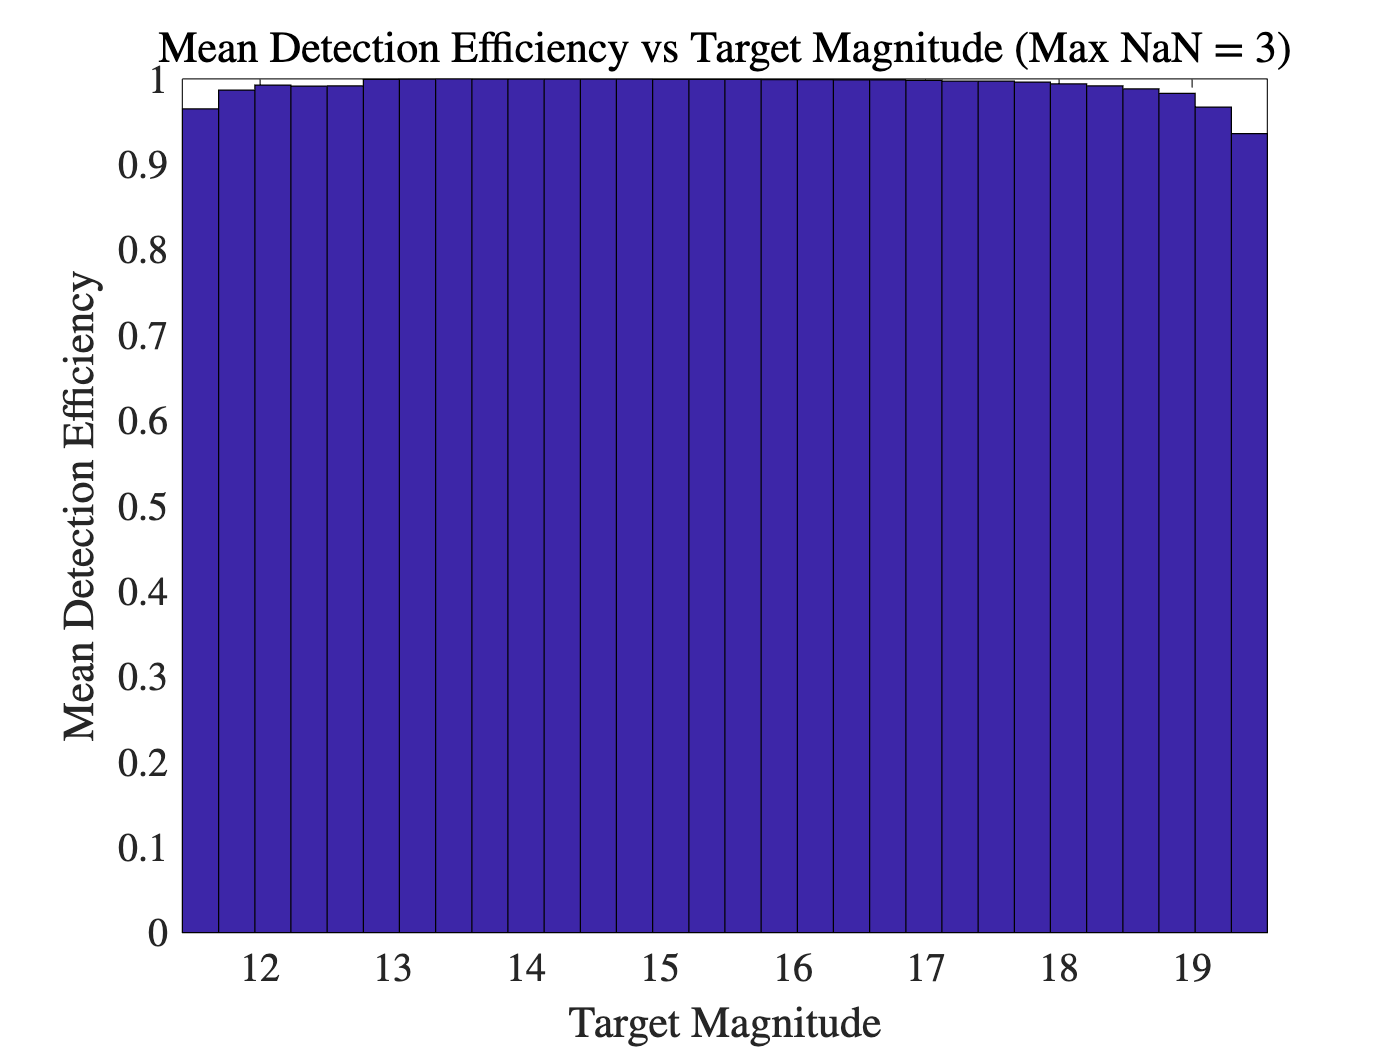



magnitude =mEff;
detection_efficiency = detEff;

% Assuming your vectors are named 'magnitude' and 'detection_efficiency'

% Define the number of bins based on the magnitude vector
num_bins = 30; % Adjust the number of bins as needed

% Create bins for the magnitude
edges = linspace(min(magnitude), max(magnitude), num_bins+1);

% Bin the detection efficiency data according to the magnitude
[~, ~, binIdx] = histcounts(magnitude, edges);

% Initialize an array to store the mean detection efficiency for each bin
mean_detection_efficiency = zeros(1, num_bins);

% Calculate the mean detection efficiency for each magnitude bin
for i = 1:num_bins
    mean_detection_efficiency(i) = mean(detection_efficiency(binIdx == i));
end

% Plot the histogram with magnitude on the x-axis and mean detection efficiency on the y-axis
figure;
bar(edges(1:end-1), mean_detection_efficiency, 'histc');

% Set axis labels and title
xlabel('Target Magnitude');
ylabel('Mean Detection Efficiency');
title('Mean Detection Efficiency vs Target Magnitude (Max NaN = 3)');

% Optionally, set the limits for the x-axis if needed
xlim([min(magnitude), max(magnitude)]);

fprintf('%i targets within  %.2f < magnitude < %.2f ',sum(binIdx == max(binIdx)),edges(max(binIdx)-1),edges(max(binIdx)))

10109 targets within  19.02 < magnitude < 19.29 

fprintf('%i targets within  %.2f < magnitude < %.2f ',sum(binIdx == max(binIdx)-1),edges(max(binIdx)-2),edges(max(binIdx)-1))

26092 targets within  18.75 < magnitude < 19.02 

### Detection efficency (Max NaN = all)


Fap =zeros(24,7);
h = waitbar(0);
detEff = [];
mEff = [];
Args.Ndet = 1*Args.Nvisits;

for Iid = 1:24 

 

    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);

    for Ivis = 2 : length(ms1)
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);

        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,Dist] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis) = length(consecutive_nan_indices)/length(light_curves(1,:));
           waitbar((Iid*Ivis)/(Nvis*24),h,sprintf('%i / %i Visits analayzed',(Iid*Ivis),(24*Nvis)))
    

    end
 



end
close(h)





fprintf('The False Positive rate as a result from NaN in a 30s exposure :%.4f',mean(mean(Fap)))

The False Positive rate as a result from NaN in a 30s exposure :0.1429

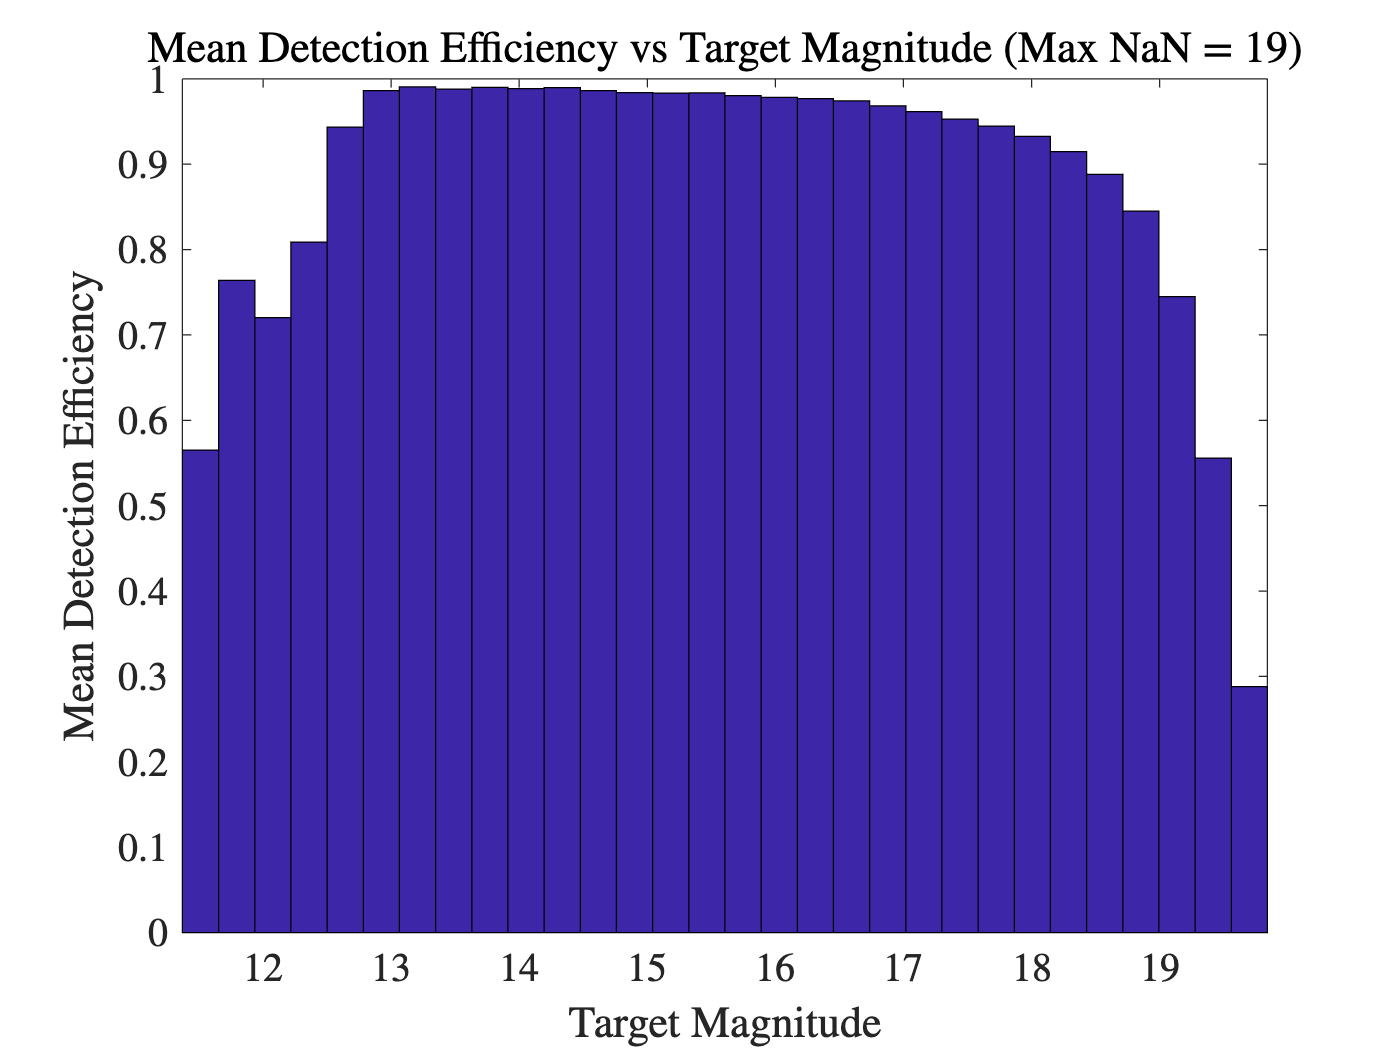



magnitude =mEff;
detection_efficiency = detEff;

% Assuming your vectors are named 'magnitude' and 'detection_efficiency'

% Define the number of bins based on the magnitude vector
num_bins = 30; % Adjust the number of bins as needed

% Create bins for the magnitude
edges = linspace(min(magnitude), max(magnitude), num_bins+1);

% Bin the detection efficiency data according to the magnitude
[~, ~, binIdx] = histcounts(magnitude, edges);

% Initialize an array to store the mean detection efficiency for each bin
mean_detection_efficiency = zeros(1, num_bins);

% Calculate the mean detection efficiency for each magnitude bin
for i = 1:num_bins
    mean_detection_efficiency(i) = mean(detection_efficiency(binIdx == i));
end

% Plot the histogram with magnitude on the x-axis and mean detection efficiency on the y-axis
figure;
bar(edges(1:end-1), mean_detection_efficiency, 'histc');

% Set axis labels and title
xlabel('Target Magnitude');
ylabel('Mean Detection Efficiency');
title('Mean Detection Efficiency vs Target Magnitude (Max NaN = 19)');

% Optionally, set the limits for the x-axis if needed
xlim([min(magnitude), max(magnitude)]);

fprintf('%i targets within  %.2f < magnitude < %.2f ',sum(binIdx == max(binIdx)),edges(max(binIdx)-1),edges(max(binIdx)))

120 targets within  19.28 < magnitude < 19.56 

fprintf('%i targets within  %.2f < magnitude < %.2f ',sum(binIdx == max(binIdx)-1),edges(max(binIdx)-2),edges(max(binIdx)-1))

44686 targets within  19.00 < magnitude < 19.28 

### Previous analysis

%% Data acquisiton
cd('~/Documents/Data/2024/08/07/proc/')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*WDJ19174*')

List = 24×1 struct array with fields:
    FileName
    Folder
    CropID


%%


LC171725 = [];
LC1725175 = [];
LC1751775 = [];
LC177518  = [];
LC181825 = [];
LC1825185 = [];
LC1851875 = [];
LC187519 = [];
LC191925  = [];
LC1925195  = [];
  LC1925195  = [];


for j = 1 :24

list1.FileName = List(j).FileName(contains(List(j).FileName,'WDJ19174'));
list1.Folder   = List(j).Folder(contains(List(j).FileName,'WDJ19174'));
list1.CropID = List(j).CropID;
ms1 =  MatchedSources.readList(list1);

        mms = ms1;

        for j = 3:length(mms)

            lc171725 = GetMagBin(mms(j),'MagMin',17.0,'MagMax',17.25);
            lc1725175 = GetMagBin(mms(j),'MagMin',17.25,'MagMax',17.5);
            lc1751775 = GetMagBin(mms(j),'MagMin',17.5,'MagMax',17.75);
            lc177518 = GetMagBin(mms(j),'MagMin',17.75,'MagMax',18);
            lc181825 = GetMagBin(mms(j),'MagMin',18.0,'MagMax',18.25);
            lc1825185 = GetMagBin(mms(j),'MagMin',18.25,'MagMax',18.5);
            lc1851875 = GetMagBin(mms(j),'MagMin',18.5,'MagMax',18.75);
            lc187519 = GetMagBin(mms(j),'MagMin',18.75,'MagMax',19.0);
            lc191925  = GetMagBin(mms(j),'MagMin',19.0,'MagMax',19.25);
            lc1925195  = GetMagBin(mms(j),'MagMin',19.25,'MagMax',19.5);



            LC171725 = [LC171725 lc171725];
            LC1725175 = [LC1725175 lc1725175];
            LC1751775 = [LC1751775 lc1751775];
            LC177518  = [LC177518 lc177518];
            LC181825 = [LC181825 lc181825];
            LC1825185 = [LC1825185 lc1825185];
            LC1851875 = [LC1851875 lc1851875];
            LC187519 = [LC187519 lc187519];
            LC191925  = [LC191925 lc191925];
            LC1925195  = [LC1925195 lc1925195];






        end

        end
binEdges = linspace(17.0, 21, 33);

binCenters = (binEdges(1:end-1) + binEdges(2:end)) / 2;
binEfficiencies = zeros(1, length(binCenters));
 Nbin1= zeros(10,1);

for Ibin = 1:length(binCenters)


    if binEdges(Ibin) >= 17 && binEdges(Ibin+1) <= 17.25
    binIndices = mean(LC171725,'omitnan') >= binEdges(Ibin) & mean(LC171725,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1751775(:,binIndices)))/20);
     Nbin1(1) = numel(binIndices);
    end

    if binEdges(Ibin) >= 17.25 && binEdges(Ibin+1) <= 17.5
    binIndices = mean(LC1725175,'omitnan') >= binEdges(Ibin) & mean(LC1725175,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1725175(:,binIndices)))/20);
     Nbin1(2) = numel(binIndices);
    end

    if binEdges(Ibin) >= 17.5 && binEdges(Ibin+1) <= 17.75
    binIndices = mean(LC1751775,'omitnan') >= binEdges(Ibin) & mean(LC1751775,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1751775(:,binIndices)))/20);
     Nbin1(3) = numel(binIndices);
    end

    if binEdges(Ibin) >= 17.75 && binEdges(Ibin+1) <= 18
    binIndices = mean(LC177518,'omitnan') >= binEdges(Ibin) & mean(LC177518,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC177518(:,binIndices)))/20);
     Nbin1(4) = numel(binIndices);
    end

    if binEdges(Ibin) >= 18 && binEdges(Ibin+1) <= 18.25
    binIndices = mean(LC181825,'omitnan') >= binEdges(Ibin) & mean(LC181825,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC181825(:,binIndices)))/20);
     Nbin1(5) = numel(binIndices);
    end
    if binEdges(Ibin) >= 18.25 && binEdges(Ibin+1) <= 18.5
    binIndices = mean(LC1825185,'omitnan') >= binEdges(Ibin) & mean(LC1825185,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1825185(:,binIndices)))/20);
     Nbin1(6) = numel(binIndices);
    end
    if binEdges(Ibin) >= 18.5 && binEdges(Ibin+1) <= 18.75
    binIndices = mean(LC1851875,'omitnan') >= binEdges(Ibin) & mean(LC1851875,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1851875(:,binIndices)))/20);
     Nbin1(7) = numel(binIndices);
    end
    if binEdges(Ibin) >= 18.75 && binEdges(Ibin+1) <= 19
    binIndices = mean(LC187519,'omitnan') >= binEdges(Ibin) & mean(LC187519,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC187519(:,binIndices)))/20);
     Nbin1(8) = numel(binIndices);
    
    end

    if binEdges(Ibin) >= 19 && binEdges(Ibin+1) <=19.25
    binIndices = mean(LC191925,'omitnan') >= binEdges(Ibin) & mean(LC191925,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC191925(:,binIndices)))/20);
     Nbin1(9) = numel(binIndices);
    end

    if binEdges(Ibin) >= 19.25 && binEdges(Ibin+1) <= 19.5
    binIndices = mean(LC1925195,'omitnan') >= binEdges(Ibin) & mean(LC1925195,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1925195(:,binIndices)))/20);
    Nbin1(10) = numel(binIndices);
    end

end




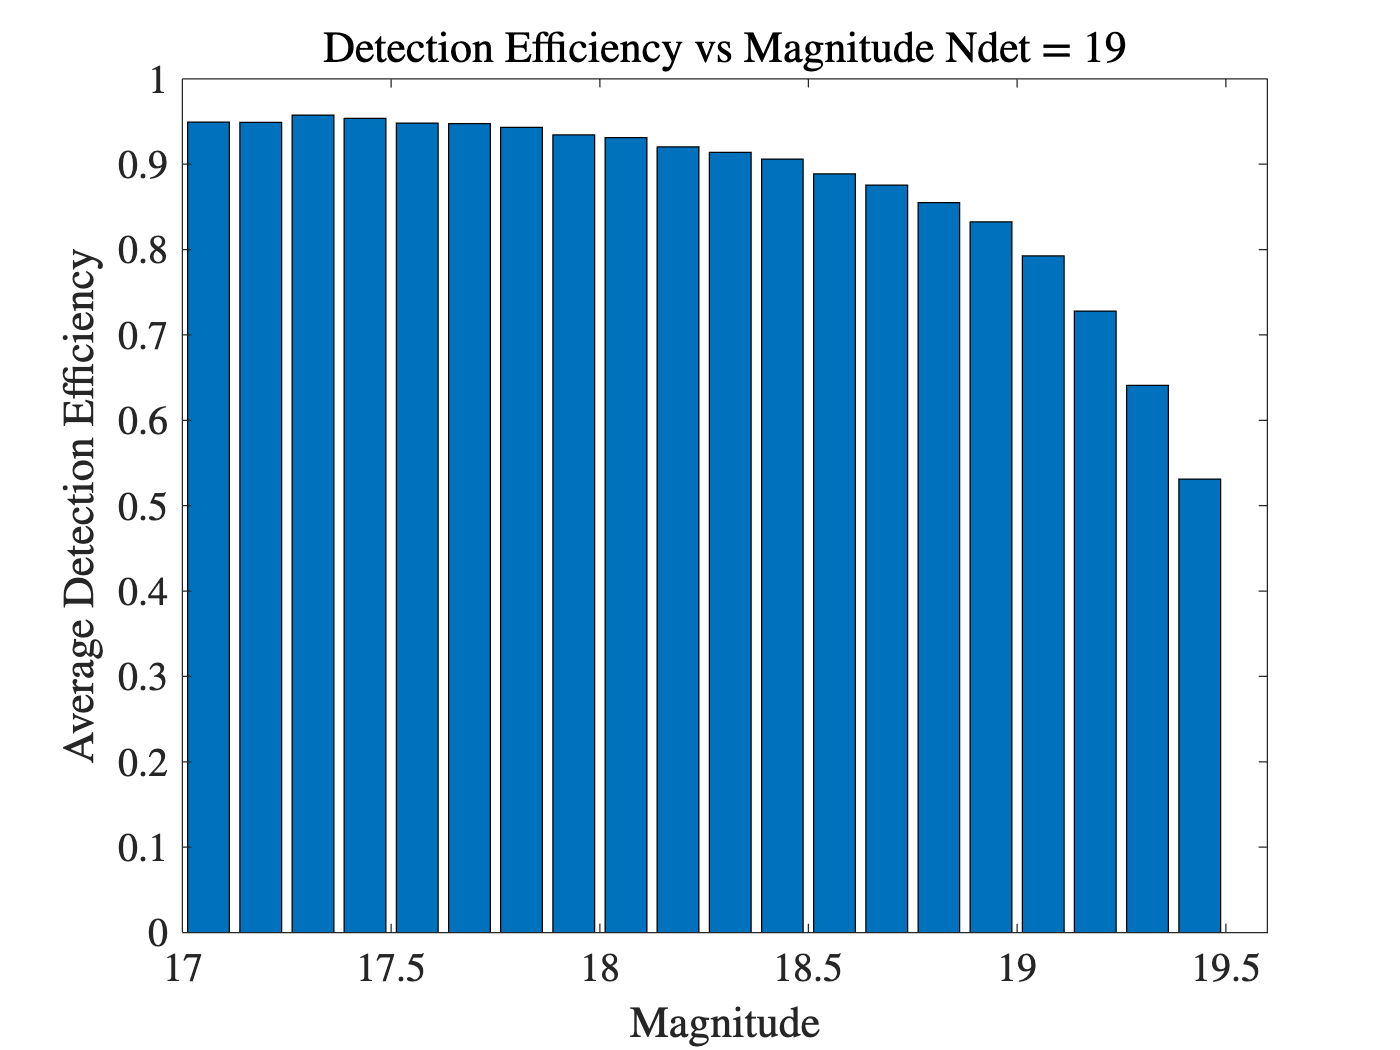

% Plot the histogram
bar(binCenters, binEfficiencies);
xlabel('Magnitude');
ylabel('Average Detection Efficiency');
title('Detection Efficiency vs Magnitude Ndet = 19');
xlim([17,19.6])

%fprintf('%i targets within  %.2f < magnitude < %.2f ',Nbin1(9),19.0,19.25)
%fprintf('%i targets within  %.2f < magnitude < %.2f ',Nbin1(10),19.25,19.5)

### Previous code with Ndet > 16


LC171725 = [];
LC1725175 = [];
LC1751775 = [];
LC177518  = [];
LC181825 = [];
LC1825185 = [];
LC1851875 = [];
LC187519 = [];
LC191925  = [];
LC1925195  = [];
  LC1925195  = [];


for j = 1 :24

list1.FileName = List(j).FileName(contains(List(j).FileName,'WDJ19174'));
list1.Folder   = List(j).Folder(contains(List(j).FileName,'WDJ19174'));
list1.CropID = List(j).CropID;
ms1 =  MatchedSources.readList(list1);

        mms = ms1;

        for j = 3:length(mms)

            lc171725 = GetMagBin(mms(j),'MagMin',17.0,'MagMax',17.25,'Ndet',16);
            lc1725175 = GetMagBin(mms(j),'MagMin',17.25,'MagMax',17.5,'Ndet',16);
            lc1751775 = GetMagBin(mms(j),'MagMin',17.5,'MagMax',17.75,'Ndet',16);
            lc177518 = GetMagBin(mms(j),'MagMin',17.75,'MagMax',18,'Ndet',16);
            lc181825 = GetMagBin(mms(j),'MagMin',18.0,'MagMax',18.25,'Ndet',16);
            lc1825185 = GetMagBin(mms(j),'MagMin',18.25,'MagMax',18.5,'Ndet',16);
            lc1851875 = GetMagBin(mms(j),'MagMin',18.5,'MagMax',18.75,'Ndet',16);
            lc187519 = GetMagBin(mms(j),'MagMin',18.75,'MagMax',19.0,'Ndet',16);
            lc191925  = GetMagBin(mms(j),'MagMin',19.0,'MagMax',19.25,'Ndet',16);
            lc1925195  = GetMagBin(mms(j),'MagMin',19.25,'MagMax',19.5,'Ndet',16);



            LC171725 = [LC171725 lc171725];
            LC1725175 = [LC1725175 lc1725175];
            LC1751775 = [LC1751775 lc1751775];
            LC177518  = [LC177518 lc177518];
            LC181825 = [LC181825 lc181825];
            LC1825185 = [LC1825185 lc1825185];
            LC1851875 = [LC1851875 lc1851875];
            LC187519 = [LC187519 lc187519];
            LC191925  = [LC191925 lc191925];
            LC1925195  = [LC1925195 lc1925195];






        end

        end
binEdges = linspace(17.0, 21, 33);

binCenters = (binEdges(1:end-1) + binEdges(2:end)) / 2;
binEfficiencies = zeros(1, length(binCenters));
Nbin = zeros(10,1);

for Ibin = 1:length(binCenters)


    if binEdges(Ibin) >= 17 && binEdges(Ibin+1) <= 17.25
    binIndices = mean(LC171725,'omitnan') >= binEdges(Ibin) & mean(LC171725,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1751775(:,binIndices)))/20);
    Nbin(1) = numel(binIndices);
    end

    if binEdges(Ibin) >= 17.25 && binEdges(Ibin+1) <= 17.5
    binIndices = mean(LC1725175,'omitnan') >= binEdges(Ibin) & mean(LC1725175,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1725175(:,binIndices)))/20);
    Nbin(2) = numel(binIndices);
    end

    if binEdges(Ibin) >= 17.5 && binEdges(Ibin+1) <= 17.75
    binIndices = mean(LC1751775,'omitnan') >= binEdges(Ibin) & mean(LC1751775,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1751775(:,binIndices)))/20);
    Nbin(3) = numel(binIndices);
    end

    if binEdges(Ibin) >= 17.75 && binEdges(Ibin+1) <= 18
    binIndices = mean(LC177518,'omitnan') >= binEdges(Ibin) & mean(LC177518,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC177518(:,binIndices)))/20);
    Nbin(4) = numel(binIndices);
    end

    if binEdges(Ibin) >= 18 && binEdges(Ibin+1) <= 18.25
    binIndices = mean(LC181825,'omitnan') >= binEdges(Ibin) & mean(LC181825,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC181825(:,binIndices)))/20);
    Nbin(5) = numel(binIndices);
    end
    if binEdges(Ibin) >= 18.25 && binEdges(Ibin+1) <= 18.5
    binIndices = mean(LC1825185,'omitnan') >= binEdges(Ibin) & mean(LC1825185,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1825185(:,binIndices)))/20);
    Nbin(6) = numel(binIndices);
    end
    if binEdges(Ibin) >= 18.5 && binEdges(Ibin+1) <= 18.75
    binIndices = mean(LC1851875,'omitnan') >= binEdges(Ibin) & mean(LC1851875,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1851875(:,binIndices)))/20);
    Nbin(7) = numel(binIndices);
    end
    if binEdges(Ibin) >= 18.75 && binEdges(Ibin+1) <= 19
    binIndices = mean(LC187519,'omitnan') >= binEdges(Ibin) & mean(LC187519,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC187519(:,binIndices)))/20);
    Nbin(8) = numel(binIndices);
    end

    if binEdges(Ibin) >= 19 && binEdges(Ibin+1) <=19.25
    binIndices = mean(LC191925,'omitnan') >= binEdges(Ibin) & mean(LC191925,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC191925(:,binIndices)))/20);
    Nbin(9) = numel(binIndices);
    end

    if binEdges(Ibin) >= 19.25 && binEdges(Ibin+1) <= 19.5
    binIndices = mean(LC1925195,'omitnan') >= binEdges(Ibin) & mean(LC1925195,'omitnan') < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(1 - sum(isnan(LC1925195(:,binIndices)))/20);
    Nbin(10) = numel(binIndices);
    end

end




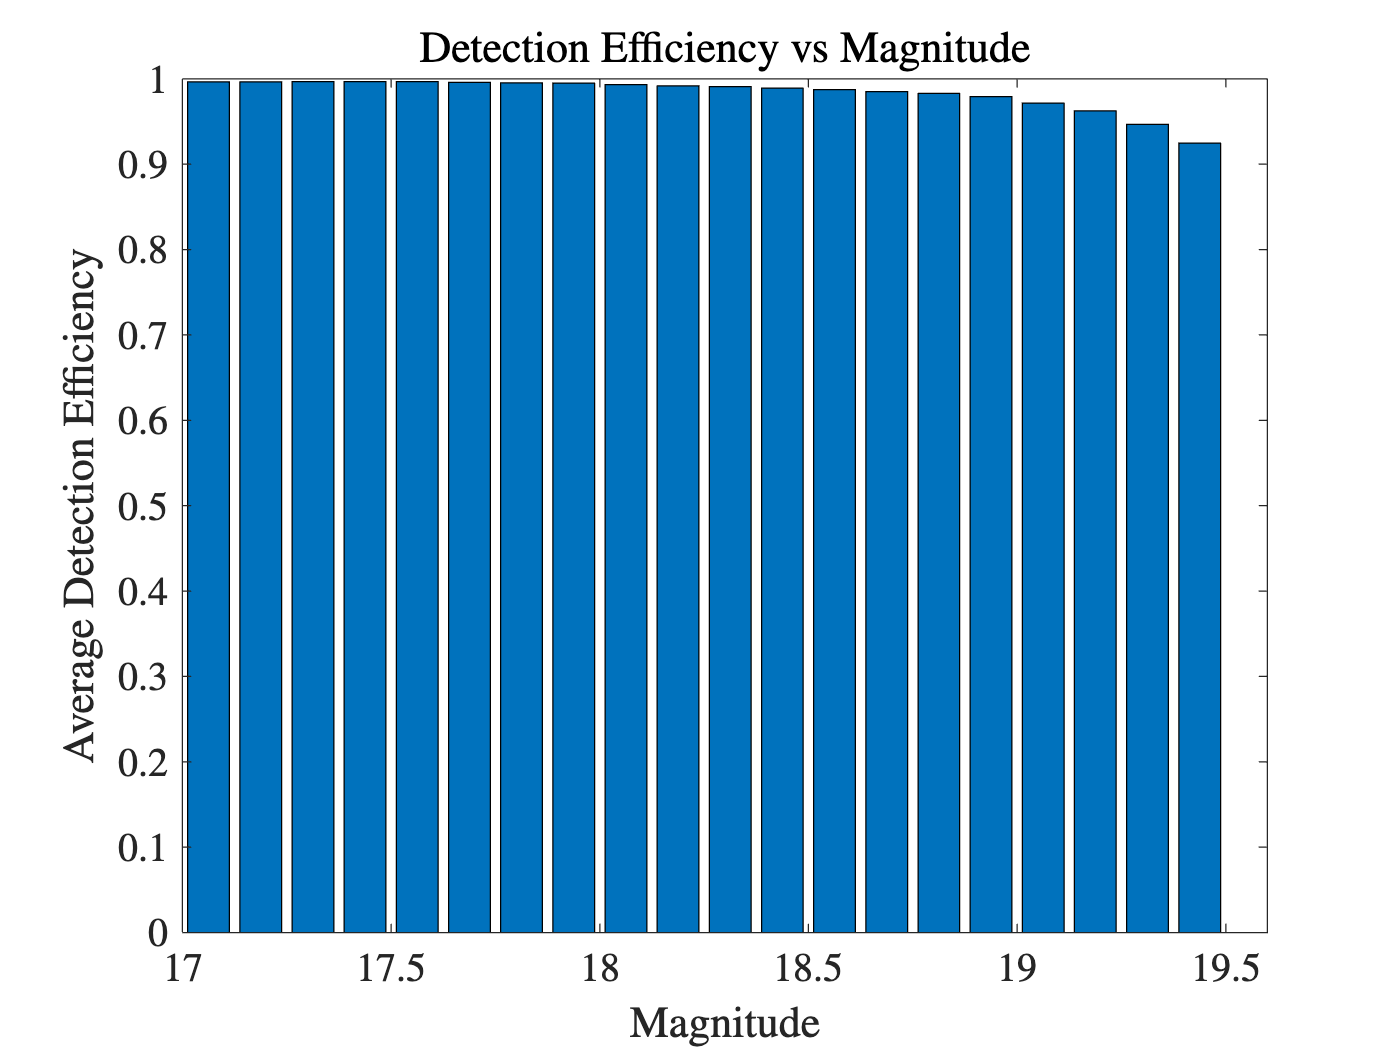

% Plot the histogram
bar(binCenters, binEfficiencies);
xlabel('Magnitude');
ylabel('Average Detection Efficiency');
title('Detection Efficiency vs Magnitude');
xlim([17,19.6])

%fprintf('%i targets within  %.2f < magnitude < %.2f ',Nbin(9),19.0,19.25)
%fprintf('%i targets within  %.2f < magnitude < %.2f ',Nbin(10),19.25,19.5)

### Examples

[Fflags,ind] = find(mean(MMS.Data.MAG_PSF,'omitnan')> 19.1);
MMS.Data.MAG_PSF(:,ind(24))

ans =           NaN
       19.174
          NaN
       19.025
       19.113
       18.927
       19.263
       19.152
       19.372
       19.203


EdgeFlags =[0
   0
   1
   1
   0
   0
   1
   1
   1
   0
   0
   1
   0
   1
   1
   1
   0
   0
   0
   1];
%[Res,EdgeVec]= getFlags1(MMS,'SrcIdx',ind(140))
%fprintf('Out of %i Overlapping points. %i are NaNs',Res.EFcounts,20 - sum(abs(isnan(MMS.Data.MAG_PSF(:,ind(140)))-logical(EdgeVec))))

Unable to resolve the name 'Res.EFcounts'.

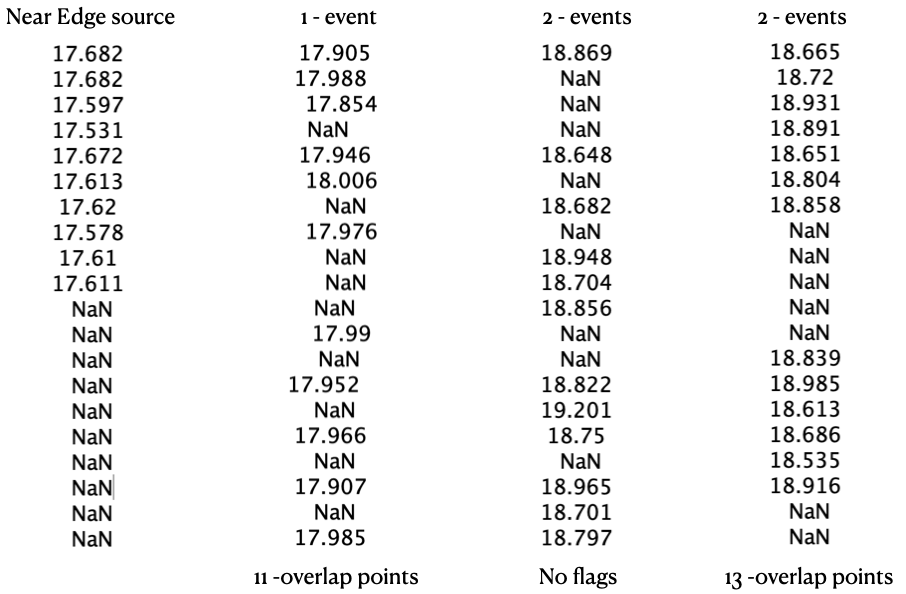

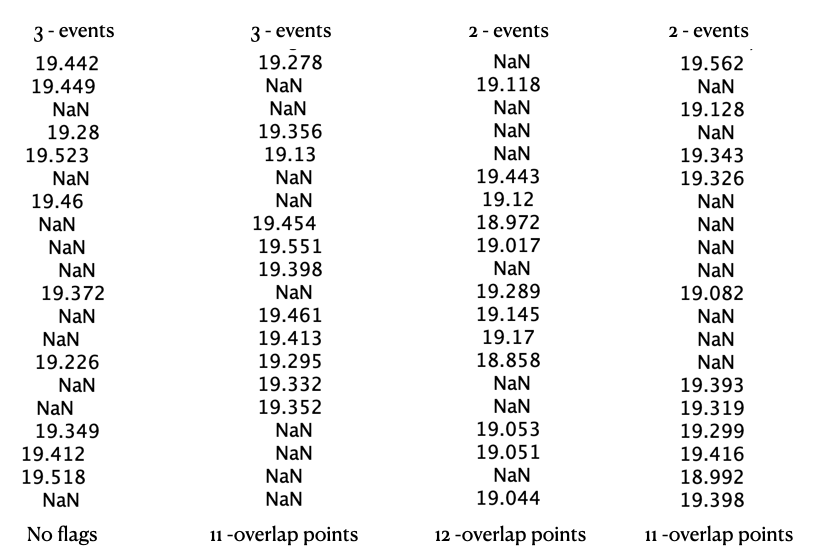

# Observation parameters.

 [Result] = ReadFromCat('~/marvin/LAST.01.05.03/2024/08/07/proc/','Field',FN,'FileNames',List(16),'CropID',16,'save_to','');

### Limiting Magnitude Vs time

 figure;
 plot(datetime(Result.JD,'convertfrom','jd'),Result.LimMag)
 ylabel("Lim Mag",  "FontAngle", "normal", "FontWeight", "normal")
xlabel("Time (UTC)",  "FontAngle", "normal", "FontWeight", "normal")
 set(gca,'Ydir','reverse')


### Airmass Vs time

figure();
plot(datetime(Result.JD,'convertfrom','jd'),Result.AM)
ylabel("AM",  "FontAngle", "normal", "FontWeight", "normal")
xlabel("Time (UTc)",  "FontAngle", "normal", "FontWeight", "normal")
set(gca,'Ydir','reverse')




